# Testing Different Text-To-Speech (TTS) Algorithm

The puporse of this experiment is to test different TTS to determine the right choice for our application. For this the following requirement were set: 

- Being able to run on CPU.

- Have real-time capabilities.

- The quality of voice needs to be clear

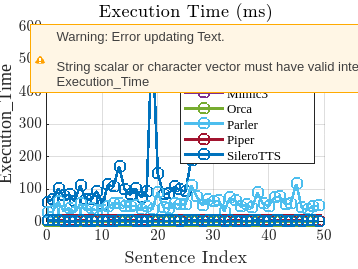

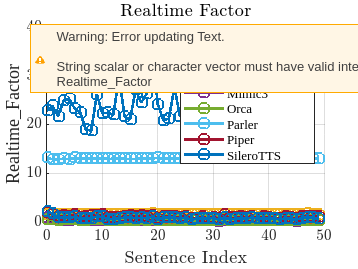

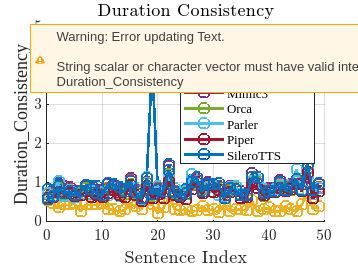

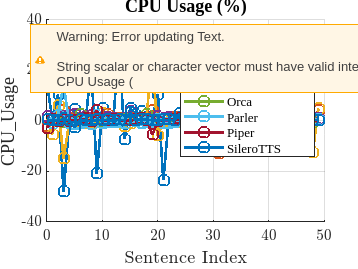

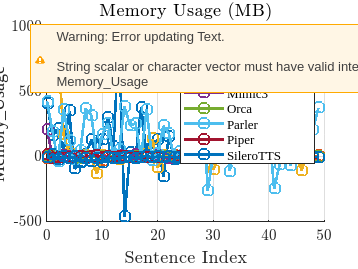

% Define the base directory where the files are located
baseDir = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/TTS/csv_files/';

% Define file names and algorithm names
files = {'Cucu_tacotron2.csv', 'espeakNG.csv', 'FastSpeech2.csv', 'Mimic3.csv', 'Orca.csv', 'Parler.csv', 'Piper.csv', 'SileroTTS.csv'};
names = {'Cucu_tacotron2', 'espeakNG', 'FastSpeech2', 'Mimic3', 'Orca', 'Parler', 'Piper', 'SileroTTS'};

% Append the base directory to each filename
files = strcat(baseDir, files);

% Metrics to be plotted
metrics = {'Execution_Time', 'Realtime_Factor', 'Duration_Consistency', 'CPU_Usage', 'Memory_Usage'};
metric_titles = {'Execution Time (ms)', 'Realtime Factor', 'Duration Consistency', 'CPU Usage (%)', 'Memory Usage (MB)'};

% Colors and markers for plots
colors = lines(numel(names)); % Use MATLAB's line color map which provides distinct colors

% Set default plotting properties
set(groot, 'DefaultTextInterpreter', 'latex');
set(groot, 'DefaultLegendInterpreter', 'latex');
set(groot, 'DefaultAxesTickLabelInterpreter', 'latex');
set(groot, 'DefaultAxesFontSize', 12);
set(groot, 'DefaultAxesFontName', 'Times New Roman');

% Loop through each metric and plot data
for i = 1:length(metrics)
    figure;
    hold on;
    all_data = [];

    for j = 1:length(files)
        % Read data
        if isfile(files{j})
            data = readtable(files{j});
            data.Properties.VariableNames = strtrim(data.Properties.VariableNames);

            % Plot if the metric column exists
            if ismember(metrics{i}, data.Properties.VariableNames)
                plot_data = data.(metrics{i});
                all_data = [all_data; plot_data];  % Collect all data for statistics
                plot(data.Sentence_Index, plot_data, '-o', 'DisplayName', names{j}, ...
                    'Color', colors(j, :), 'LineWidth', 2, 'MarkerSize', 8);
            end
        end
    end

    grid on;
    title(metric_titles{i}, 'FontSize', 14, 'FontWeight', 'bold');
    xlabel('Sentence Index', 'FontSize', 14);
    ylabel(metrics{i}, 'FontSize', 14);
    legend show;
    hold off;

    % Save as EPS
    print(['plot_' metrics{i}], '-depsc');
end


% Reset default plotting properties
set(groot, 'DefaultTextInterpreter', 'none');
set(groot, 'DefaultLegendInterpreter', 'none');
set(groot, 'DefaultAxesTickLabelInterpreter', 'none');
set(groot, 'DefaultAxesFontSize', 'remove');
set(groot, 'DefaultAxesFontName', 'remove');

% Metrics to be plotted
metrics = {'Execution_Time', 'Realtime_Factor', 'Duration_Consistency', 'CPU_Usage', 'Memory_Usage'};
metric_titles = {'Execution Time (ms)', 'Realtime Factor', 'Duration Consistency', 'CPU Usage (%)', 'Memory Usage (MB)'};

metric_data = struct;

% Initialize data structure for metrics data and best performance tracking
for i = 1:length(metrics)
    metric_data.(metrics{i}) = table('Size', [length(names), 4], 'VariableTypes', repmat("double", 1, 4), 'VariableNames', {'Best', 'Worst', 'Average', 'StdDev'}, 'RowNames', names);
end

% Process each file and compute statistics
for j = 1:length(files)
    if isfile(files{j})
        data = readtable(files{j});
        data.Properties.VariableNames = strtrim(data.Properties.VariableNames);
        for i = 1:length(metrics)
            if ismember(metrics{i}, data.Properties.VariableNames)
                plot_data = data.(metrics{i});
                metric_data.(metrics{i}).Best(j) = min(plot_data);
                metric_data.(metrics{i}).Worst(j) = max(plot_data);
                metric_data.(metrics{i}).Average(j) = mean(plot_data);
                metric_data.(metrics{i}).StdDev(j) = std(plot_data);
            end
        end
    end
end

% Identify and display the best performance
for i = 1:length(metrics)
    % Find the minimum average performance
    [~, idx] = min(metric_data.(metrics{i}).Average);
    best_algorithm = names{idx};
    fprintf('\n%s - Best Algorithm: %s (Average: %.2f)\n', metric_titles{i}, best_algorithm, metric_data.(metrics{i}).Average(idx));
end

Execution Time (ms) - Best Algorithm: Mimic3 (Average: 1.27)

Realtime Factor - Best Algorithm: Mimic3 (Average: 0.31)

Duration Consistency - Best Algorithm: FastSpeech2 (Average: 0.38)

CPU Usage (%) - Best Algorithm: FastSpeech2 (Average: -0.40)

Memory Usage (MB) - Best Algorithm: SileroTTS (Average: -3.42)



% Display each metric's table
for i = 1:length(metrics)
    fprintf('\nMetric: %s\n', metric_titles{i});
    disp(metric_data.(metrics{i}));
end


Metric: Execution Time (ms)


                      Best     Worst     Average     StdDev  
                      _____    ______    _______    _________

    Cucu_tacotron2    53.06    586.96    115.31        99.311
    espeakNG           2.01      2.02     2.011     0.0030305
    FastSpeech2        2.66      3.01     2.696      0.077037
    Mimic3             1.15      2.21    1.2722       0.14859
    Orca               1.18      1.61    1.3624       0.10711
    Parler            29.33    117.44     54.49        19.397
    Piper              3.39      4.37    3.7814       0.28433
    SileroTTS          2.22         5    3.2662       0.62874




Metric: Realtime Factor


                      Best     Worst    Average     StdDev 
                      _____    _____    _______    ________

    Cucu_tacotron2     18.8    36.03     23.89       3.6042
    espeakNG            0.3      0.9    0.5156      0.14099
    FastSpeech2        1.53     1.73    1.5482     0.044432
    Mimic3             0.19     0.95    0.3086       0.1109
    Orca               0.24     0.59    0.3638     0.081863
    Parler            12.81    13.56    13.072      0.13432
    Piper              0.71     2.01    1.0898      0.25575
    SileroTTS          0.49     2.22    0.8304      0.28918




Metric: Duration Consistency


                      Best    Worst    Average    StdDev 
                      ____    _____    _______    _______

    Cucu_tacotron2    0.59    4.07     1.0052     0.63554
    espeakNG          0.63    1.47      0.856      0.1621
    FastSpeech2       0.23    0.73     0.3754     0.10502
    Mimic3            0.63    1.51      0.904     0.16864
    Orca              0.58    1.37      0.808     0.15419
    Parler            0.56    1.35     0.8412     0.17512
    Piper             0.52    1.27     0.7524     0.14405
    SileroTTS         0.57     1.5     0.8616     0.18934




Metric: CPU Usage (%)


                      Best     Worst    Average    StdDev 
                      _____    _____    _______    _______

    Cucu_tacotron2    -28.1    30.4     1.4296       11.96
    espeakNG            -13     4.2      0.574       2.771
    FastSpeech2       -14.8    25.6     -0.404      5.0254
    Mimic3              0.3       4      1.316     0.86292
    Orca               -1.1     3.3      0.392     0.84632
    Parler             -1.4    14.9      0.074      2.3511
    Piper              -5.4     4.1      0.376      1.2556
    SileroTTS          -2.4     3.4      0.532     0.91505




Metric: Memory Usage (MB)


                       Best      Worst     Average    StdDev
                      _______    ______    _______    ______

    Cucu_tacotron2    -459.56    920.13     104.34    240.63
    espeakNG           -23.32     13.97     0.0766    5.2629
    FastSpeech2       -127.72    813.27     43.776    179.26
    Mimic3             -15.09    211.63     6.7174    30.436
    Orca                -8.59     14.79     0.3368    3.8425
    Parler            -260.48    656.55     154.38    194.64
    Piper              -11.82     22.96     -0.006    6.4563
    SileroTTS          -42.79     22.54    -3.4222    10.745



Barplots

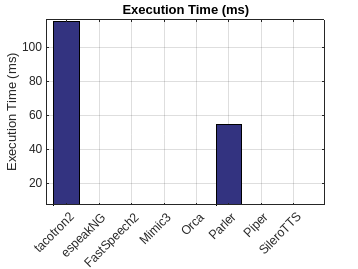

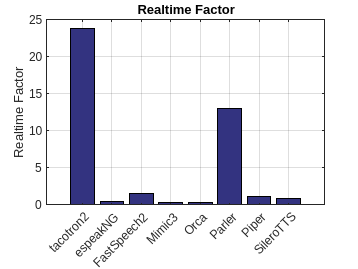

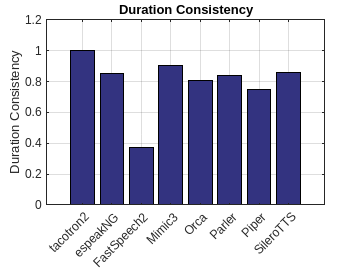

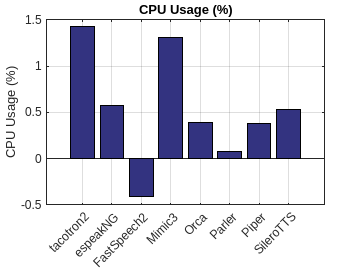

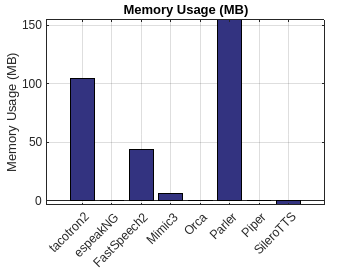

% Define the base directory where the files are located
baseDir = '/home/rasmus/Desktop/Master/MasterThesisGit/standalone_tests/TTS/csv_files/';

% Define file names and algorithm names
files = {'Cucu_tacotron2.csv', 'espeakNG.csv', 'FastSpeech2.csv', 'Mimic3.csv', 'Orca.csv', 'Parler.csv', 'Piper.csv', 'SileroTTS.csv'};
names = {'tacotron2', 'espeakNG', 'FastSpeech2', 'Mimic3', 'Orca', 'Parler', 'Piper', 'SileroTTS'};

% Append the base directory to each filename
fullFilePaths = fullfile(baseDir, files);

% Metrics to be plotted
metrics = {'Execution_Time', 'Realtime_Factor', 'Duration_Consistency', 'CPU_Usage', 'Memory_Usage'};
metric_titles = {'Execution Time (ms)', 'Realtime Factor', 'Duration Consistency', 'CPU Usage (%)', 'Memory Usage (MB)'};

% Create a figure for each metric
for i = 1:length(metrics)
    dataMatrix = [];
    
    % Read and process each file
    for j = 1:length(fullFilePaths)
        if isfile(fullFilePaths{j})
            dataTable = readtable(fullFilePaths{j}, 'PreserveVariableNames', true);
            if ismember(metrics{i}, dataTable.Properties.VariableNames)
                % Extract the relevant metric data
                metricData = dataTable.(metrics{i});
                dataMatrix = [dataMatrix, nanmean(metricData)];  % Calculate average and handle NaNs
            else
                dataMatrix = [dataMatrix, NaN];  % Append NaN if metric not available
            end
        else
            dataMatrix = [dataMatrix, NaN];  % Append NaN if file not found
        end
    end
    
    % Generate the bar plot
    figure;
    bar(dataMatrix, 'FaceColor', [0.2 0.2 0.5]);
    set(gca, 'XTickLabel', names, 'XTickLabelRotation', 45);
    ylabel(metric_titles{i});
    title(strrep(metric_titles{i}, '_', ' '));
    grid on;
    
    % Save the plots as PNG
    saveas(gcf, fullfile(baseDir, [metrics{i} '_bar_plot.png']));
end